# Step 2 - Robust Control Analysis

# What is Robust Control?

A robust system is a system capable of meeting requirements (stability or performance measures) even in the presence or model and/or disturbance uncertainty. Robust Control is an approach to designing a system in a way that can handle uncertainty.

Reality: Models are mostly WRONG! The key question is if the model is good enough??? Remember that mathematical models are imperfect representations of real life systems

So, Why are models wrong?

- Complex dynamics

- Uncertain driving forces

- Linear models sacrifice realism for simplicity

- Stochastic events - noise/degradation

- Process variations

To clarify, Robust Control is NOT a specific type of controller like PID or LQR. Robust Control is a **DESIGN METHOD**. There exist many different design methods for designing controllers for robustness: $H_{\infty }$, $\mu$ synthesis, etc.

The major steps involved in designing a robust system are:

- Understand uncertainty and represent it in your model

- Analyze your system to see if it is robust to the uncertainties (analysis)

- If not sufficiently robust, make changes to it so that it is robust (synthesis)

Open loop transfer function


$$G\left(s\right)=\frac{0\ldotp 38\left(s^2 +0\ldotp 1s+0\ldotp 55\right)}{s\left(s+1\right)\left(s^2 +0\ldotp 06s+0\ldotp 5\right)}$$


% Define the transfer function
s = tf('s');
G = 0.38*(s^2 + 0.1*s + 0.55)/(s*(s+1)*(s^2 + 0.06*s + 0.5));

% Get the classical gain and phase margins
margin(G)

Additional gain by itself doesn't result in instability

addgain = 15; % 15 dB of extra gain
step(feedback(G * 10^(addgain/20),1))

Additional phase by itself (less than the phase margin) doesn't result in instability

adddelay = 2; % 2 seconds of additional delay
step(feedback(G * exp(-s*adddelay),1))

But, small increases in **both** gain and phase result in instability

addgain = 3; % 3 dB of extra gain
adddelay = 0.2; % 0.2 seconds of additional delay
step(feedback(G * 10^(addgain/20) * exp(-s*adddelay),1))

Disk margin accounts for simultaneous gain and phase perturbations

DM = diskmargin(G)
clf, nyquist(G), hold all;
diskmarginplot(DM.GainMargin,'nyquist')

# Modeling Uncertainty

We need a way to represent uncertainty, i.e. errors in the model. Often uncertainty can be bound. For example, consider model variations along the frequency spectrum: you might have more confidence in the model at low frequencies (and the uncertainty grows with frequency), then we need less margin at low frequency behaviours.

## Building and Manipulating Uncertain Models

This example shows how to use Robust Control Toolbox™ to build uncertain state-space models and analyze the robustness of feedback control systems with uncertain elements. 

We will show how to specify uncertain physical parameters and create uncertain state-space models from these parameters. You will see how to evaluate the effects of random and worst-case parameter variations using the functions `usample` and `robstab`.

## Two-Cart and Spring System

In this example, we use the following system consisting of two frictionless carts connected by a spring `k`:

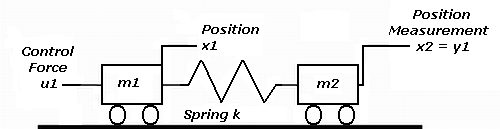

**Figure 1:** Two-cart and spring system.

The control input is the force `u1` applied to the left cart. The output to be controlled is the position `y1` of the right cart. The feedback control is of the following form:


$$u_1 = C(s) (r-y_1)$$


In addition, we use a triple-lead compensator:


$$C(s)=100 (s+1)^3/(0.001s+1)^3$$


We create this compensator using this code:

s = zpk('s'); % The Laplace 's' variable
C = 100*ss((s+1)/(.001*s+1))^3;

## Block Diagram Model

The two-cart and spring system is modeled by the block diagram shown below.

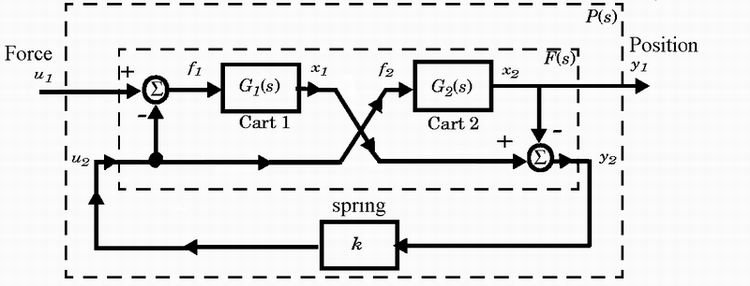

**Figure 2:** Block diagram of two-cart and spring model. 

## Uncertain Real Parameters

The problem of controlling the carts is complicated by the fact that the values of the spring constant `k` and cart masses `m1,m2` are known with only 20% accuracy: $k=1.0 \pm 20\%$ , $m1=1.0 \pm 20\%$ , and $m2=1.0 \pm 20\%$. To capture this variability, we will create three uncertain real parameters using the `ureal` function:

k = ureal('k',1,'percent',20);
m1 = ureal('m1',1,'percent',20);
m2 = ureal('m2',1,'percent',20);

## Uncertain Cart Models

We can represent the carts models as follows: 


$$G_1(s) = \frac{1}{m_1 s^2}, \;\;\; G_2(s) = \frac{1}{m_2 s^2}$$


Given the uncertain parameters `m1` and `m2`, we will construct uncertain state-space models (USS) for G1 and G2 as follows:

G1 = 1/s^2/m1;
G2 = 1/s^2/m2;

## Uncertain Model of a Closed-Loop System

First we'll construct a plant model `P` corresponding to the block diagram shown above (`P` maps u1 to y1):

% Spring-less inner block F(s)
F = [0;G1]*[1 -1]+[1;-1]*[0,G2]

Connect with the spring k 

P = lft(F,k)

The feedback control u1 = C*(r-y1) operates on the plant `P` as shown below:

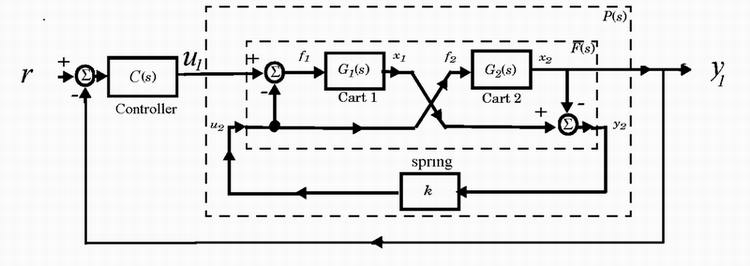

**Figure 3:** Uncertain model of a closed-loop system. 

We'll use the `feedback` function to compute the closed-loop transfer from r to y1. 

% Uncertain open-loop model is
L = P*C

Uncertain closed-loop transfer from r to y1 is

T = feedback(L,1)

Note that since `G1` and `G2` are uncertain, both `P` and `T` are uncertain state-space models.

## Extracting the Nominal Plant

The nominal transfer function of the plant is

Pnom = zpk(P.nominal)

## Nominal Closed-Loop Stability

Next, we evaluate the nominal closed-loop transfer function `Tnom`, and then check that all the poles of the nominal system have negative real parts: 

Tnom = zpk(T.nominal);
maxrealpole = max(real(pole(Tnom)))

## Robust Stability Margin

Will the feedback loop remain stable for all possible values of `k,m1,m2` in the specified uncertainty range? We can use the `robstab` function to answer this question rigorously.

% Show report and compute sensitivity
opt = robOptions('Display','on','Sensitivity','on');
[StabilityMargin,wcu] = robstab(T,opt);

The report indicates that the closed loop can tolerate up to three times as much variability in `k,m1,m2` before going unstable. It also provides useful information about the sensitivity of stability to each parameter. The variable `wcu` contains the smallest destabilizing parameter variations (relative to the nominal values).

wcu

## Worst-Case Performance Analysis

Note that the peak gain across frequency of the closed-loop transfer `T` is indicative of the level of overshoot in the closed-loop step response. The closer this gain is to 1, the smaller the overshoot. We use `wcgain` to compute the worst-case gain `PeakGain` of `T` over the specified uncertainty range.

[PeakGain,wcu] = wcgain(T);
PeakGain

Substitute the worst-case parameter variation `wcu` into `T` to compute the worst-case closed-loop transfer `Twc`.

Twc = usubs(T,wcu);         % Worst-case closed-loop transfer T

Finally, pick from random samples of the uncertain parameters and compare the corresponding closed-loop transfers with the worst-case transfer `Twc`.

Trand = usample(T,4);         % 4 random samples of uncertain model T
clf
subplot(211), bodemag(Trand,'b',Twc,'r',{10 1000});  % plot Bode response
subplot(212), step(Trand,'b',Twc,'r',0.2);           % plot step response

**Figure 4:** Bode diagram and step response. 

In this analysis, we see that the compensator C performs robustly for the specified uncertainty on k,m1,m2.

# Build Tunable Control System Model with Uncertain Parameters

This example shows how to construct a generalized state-space (`genss`) model of a control system that has both tunable and uncertain parameters. You can use `systune` to tune the tunable parameters of such a model to achieve performance that is robust against the uncertainty in the system.

For this example, the plant is a mass-spring-damper system. The input is the applied force, *F*, and the output is *x*, the position of the mass. 

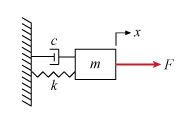

In this system, the mass *m*, the damping constant *c*, and the spring constant *k* all have some uncertainty. Use uncertain `ureal` parameters to represent these quantities in terms of their nominal or most probable value and a range of uncertainty around that value.

um = ureal('m',3,'Percentage',40);
uc = ureal('c',1,'Percentage',20);
uk = ureal('k',2,'Percentage',30);

The transfer function of a mass-spring-damper system is a second-order function given by:


$$G\left( s \right) = {1 \over {m{s^2} + cs + k}}.$$


Create this transfer function in MATLAB® using the uncertain parameters and the `tf` command. The result is an uncertain state-space (`uss`) model.

G = tf(1,[um uc uk])

Suppose you want to control this system with a PID controller, and that your design requirements include monitoring the response to noise at the plant input. Build a model of the following control system.

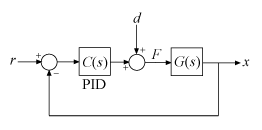

Use a tunable PID controller, and insert an analysis point to provide access to the disturbance input.

C0 = tunablePID('C','PID');
d = AnalysisPoint('d');

Connect all the components to create the control system model.

T0 = feedback(G*d*C0,1)
T0.InputName = 'r';
T0.OutputName = 'x';

`T0` is a generalized state-space (`genss`) model that has both tunable and uncertain blocks. In general, you can use `feedback` and other model interconnection commands, such as `connect`, to build up models of more complex tunable and uncertain control systems from fixed-value LTI components, uncertain components, and tunable components.

When you plot system responses of a `genss` model that is both tunable and uncertain, the plot displays multiple responses computed at random values of the uncertain components. This sampling provides a general sense of the range of possible responses. All plots use the current value of the tunable components.

bodeplot(T0)

When you extract responses from a tunable and uncertain `genss` model, the responses also contain both tunable and uncertain blocks. For example, examine the loop transfer function at the disturbance input.

S0 = getLoopTransfer(T0,'d')
bodeplot(S0)

You can now create tuning goals and use `systune` to tune the PID controller coefficients of T0. When you do so, `systune` automatically tunes the coefficients to maximize performance over the full range of uncertainty. 

# Understanding Disk Margin

Given an open loop system

s = tf('s');
L = 20/(s^3 + 10*s^2 + 10*s + 10)

The classical gain and phase margins are:

[GainMargin, PhaseMargin] = margin(L)

But, if we check the disk margin

diskmargin(L)

Lets say the requirements were: gain margin > 3 and phase margin > 30 deg. So from the classical analysis, our system seems to be good! If it didn't, we would neet to change the system - either the controller part, or the filters, or maybe the plant itself.

The more margin you have in the design, the more robust your system is to uncertainty and variations. You will have more confidence that the real system will be stable! We can assess how much margin our closed loop system has, by adding some variation inline with L.

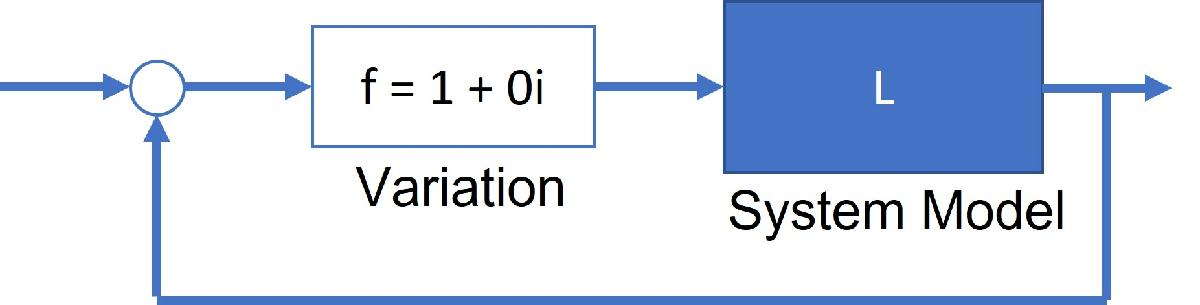

The amount of variation it takes for the closed loop system to go unstable is how much margin we have in that direction. We will vary a combination of BOTH gain and phase. We will do that by multiplying the plant by a value f (f is a single complex number - with real and imaginary components).

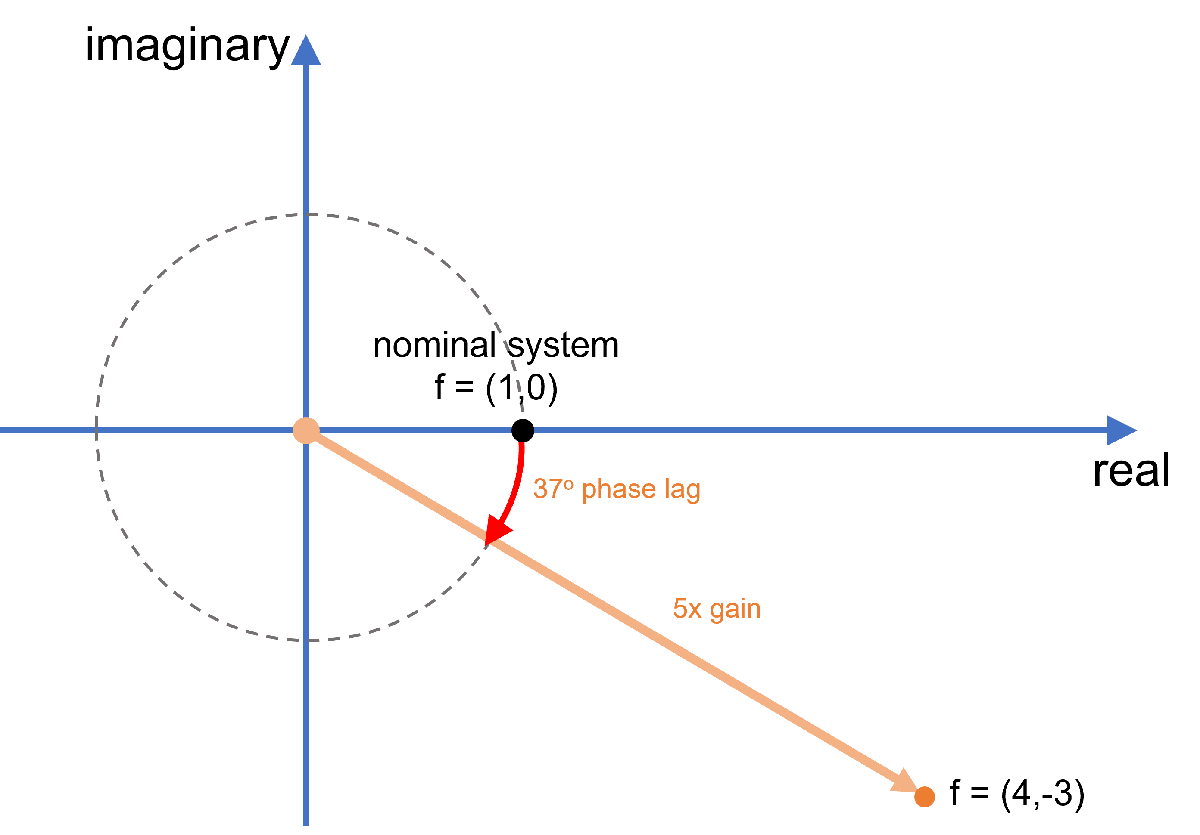

Create a multiplier f

f = 4 - 3*1i;

Plot the Bode diagram for L and f*L

bode(L, f*L);
legend('L', 'f*L');
set(findall(gcf,'type','line'),'linewidth',3);

not_realizable = f*L

Bode plots are nice because gain and phase are separated out and it is pretty easy to see the added gain or the added phase directly. However, disk margins have a nice, intuitive representation in the complex plane, so from now on, we are going to look at our system response on a Nyquist plot.

nyquist(L)
set(findall(gcf,'type','line'),'linewidth',2);

As the name suggests, disk margin defines margins as a disk in the complex plane, rather than just 2 points. We can define a disk that is able to fit entirely withing the stable region and includes the nominal point f = 1. Within this disk, every single combination of gain and phase produces a stable closed loop system. So now we can say the the margin in our design is the distance between the nominal system and the edge of the disk. As long as the real system variation falls within this disk, then we have confidence that our system will be stable. This is nice because it takes a combination of phase and gain rather than just one or the other like we had with classical margins.

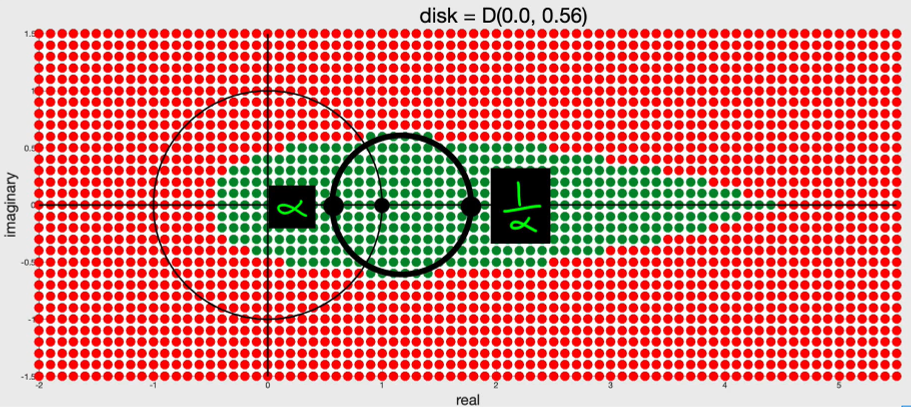

The size and location of the disk, is defined as a function of two parametrers: e and $\alpha$

- e is the **SKEW** of the disk (think of it as how far the center of the disk is, relative to the point  f = 1)

- Think of $\alpha$ as a measure of the size of the disk

So, if we choose a value for skew, then $\alpha$ is the maximum disk size that only includes stable variations. The value of e that you choose is based on the expectation of how gain in the real system is going to vary. If you think gain in the real system is more likely to be higher than what your model claims, you might want to choose a more positive e or viceversa. If you have no idea, you might want to choose e = 0. This balances the gain equally on either side of f = 1.

So now we can describe the boundary of this maximum disk as having a lower and upper gain margin and a lower and upper phase margin.

Or we can say that given a specific skew e, the maximum disk margin is $\alpha$

Revisiting the numbers we had when we calculated the disk margin (default e=0)

diskmargin(L)

For e = 5

diskmargin(L,5)

It might be worthwhile to check both disk margin and gain and phase margin because they are going to tell you slightly different things. Overall margins are just a design tool. It is a way to ensure that your design is robust to the variations and uncertainty that you expect in the real system. Disk margin is a** MUCH BETTER** indicator of robustness when we apply it to multivariable systems.

## Disk Margin and Smallest Destabilizing Perturbation

This example shows how to interpret the `WorstPerturbation` field in the structure returned by [`diskmargin`](docid:robust_ref.mw_db4e8512-b4c5-46e3-9b06-e0d7a3fb6232), the smallest gain and phase variation that results in closed-loop instability. 

## Disk Margin as Range of Allowable Gain and Phase Variations

Compute the disk margins of a SISO feedback loop with open-loop response `L`. 

L = tf(25,[1 10 10 10]);
DM = diskmargin(L);

The disk-based margins define a range of "safe" gain and phase variations for which the feedback loop remains stable. The `diskmarginplot` command lets you visualize this range as a region in the gain-phase plane. As long as gain and phase variations stay within the shaded region, the closed-loop system `feedback(L,1)` remains stable. 

diskmarginplot(DM.GainMargin)

`diskmargin` models gain and phase variations as a complex-valued multiplicative factor `F` applied to the nominal loop transfer `L`. The set of `F` values is a disk whose intersection with the real axis is the interval `DM.GainMargin`. (See [Stability Analysis Using Disk Margins](docid:robust_ug.mw_a81dfae6-e5fb-436c-b6c7-b86e29ca8c2d).) `diskmarginplot` can also plot the `F` disk.

diskmarginplot(DM.GainMargin,'disk')

`diskmargin` also computes the smallest variation that destabilizes the feedback loop, returned in the field `DM.WorstPerturbation`. This variation is returned as a state-space model that realizes the destabilizing gain and phase variation. When you multiply L by this perturbation, the resulting closed-loop system has an undamped pole at the frequency returned in `DM.Frequency`.

WC = DM.WorstPerturbation;
CL = feedback(L*WC,1);
damp(CL)

Verify that the gain and phase variation of the destabilizing perturbation mark a boundary point for the range of "safe" gain and phase variations. To do so, compute the gain and phase of `WC` at `DM.Frequency`. 

hWC = freqresp(WC,DM.Frequency);

GM = mag2db(abs(hWC))
PM = 180/pi * abs(angle(hWC))
diskmarginplot(DM.GainMargin)
line(GM,PM,'Color','k','Marker','+','MarkerSize',8,'LineWidth',3,'HandleVisibility','off')
text(GM+.1,PM+1,sprintf('Gain and phase of WC\n      at f = %.5g',DM.Frequency))

## Nyquist Interpretation

The statement that the perturbation `WC` drives the closed-loop system unstable is equivalent to saying that the Nyquist plot of `L*WC` touches the critical point at the frequency `DM.Frequency`. (See [Stability Analysis Using Disk Margins](docid:robust_ug.mw_a81dfae6-e5fb-436c-b6c7-b86e29ca8c2d).)  The following plot shows the Nyquist plots of `L` and `L*WC`. The crosses on each plot mark the response at `DM.Frequency`, and confirm that the response of `L*WC` is –1 at this frequency. 

figure(2), clf
hL = freqresp(L,DM.Frequency);
nyquist(L,L*WC), title('Open-loop response')
legend('L','L*WC')
axis([-2 2 -2 2])
line(-1,0,'Color','r','Marker','+','MarkerSize',8,...
          'LineWidth',3,'HandleVisibility','off')
line(real(hL),imag(hL),'Color','k','Marker','+',...
          'MarkerSize',8,'LineWidth',3,'HandleVisibility','off')
text(real(hL)+0.05,imag(hL)-0.2,sprintf('f = %.5g',DM.Frequency))
line([real(hL) -1],[imag(hL) 0],'Color','k','LineStyle',':',...
          'LineWidth',2,'HandleVisibility','off')

The perturbation `WC` is dynamic and its Nyquist plot hugs the boundary of the disk of `F` values. The point of contact is the frequency `DM.Frequency` where the disk margin is weakest. The following plot uses `diskmarginplot` to render the disk of allowable gain and phase variations on the Nyquist plane, superimposing the response of the perturbation `WC`. The black cross again marks the response at `DM.Frequency`. 

hWC = freqresp(WC,DM.Frequency);

diskmarginplot(DM.GainMargin,'disk')
hold on
nyquist(WC)
hold off
axis([0.6 1.6 -0.6 0.6])
line(real(hWC),imag(hWC),'Color','k','Marker','+',...
   'MarkerSize',8,'LineWidth',3,'HandleVisibility','off')
text(real(hWC)+0.02,imag(hWC)-0.05,sprintf('f = %.5g',DM.Frequency))

Equivalently, this frequency is where the Nyquist plot of `L` touches the exclusion region associated with the disk margins `DM`. The following plot shows the disk of variations with the Nyquist plot of `L`. The black cross marks the response of `L` at `DM.Frequency`.

diskmarginplot(DM.GainMargin,'nyquist')
hold on
nyquist(L)
hold off
axis([-2 0 -1 1])
line(real(hL),-imag(hL),'Color','k','Marker','+',...
        'MarkerSize',8,'LineWidth',3,'HandleVisibility','off')
text(real(hL)+0.05,-imag(hL)+0.05,sprintf('f = %.5g',DM.Frequency))

Thus, the disk `F` represents a region in the Nyquist plane that the response of `L` cannot enter while preserving closed-loop stability. At the critical frequency `DM.Frequency`, the frequency at which the gain and phase margins are smallest, the Nyquist plot of `L` just touches the disk.

# Model Gain and Phase Uncertainty in Feedback Loops

This example shows how to model gain and phase uncertainty in feedback loops using the `umargin` control design block. The example also shows how to check a feedback loop for robust stability against such uncertainty.

## Modeling Gain and Phase Uncertainty

Consider a SISO feedback loop with open-loop transfer function

$L=\frac{3\ldotp 5}{s^3 +{2s}^2 +3s}$.

L = tf(3.5,[1 2 3 0]);
bode(L)
grid on

Due to plant uncertainty and other sources of variability, the loop gain and phase are subject to fluctuations. In general, you can quantify the amount of uncertainty through experimenting on your system, or approximate it based on insight or experience. For this example, suppose that the open-loop gain can increase or decrease by 50%, and the phase by ±30*°*. You can use the `umargin` block to model such uncertainty. `umargin` represents the variation as an uncertain multiplicative factor `F` with nominal value 1. The set of values *F* can take captures the gain and phase uncertainty you specify. 

To create the `umargin` block, use `getDGM` to compute the smallest uncertainty disk that captures the gain and phase variation you want to represent. Use the output of `getDGM` to create *F*. 

DGM = getDGM(1.5,30,'tight');
F = umargin('F',DGM)

Visualize *F* to see the range of values taken by this factor (right) and the range of gain and phase variations it models by `F` (left). 

plot(F)

The plots show that the gain can vary between 47% and 150% of its nominal value (assuming no phase variation) and the phase can vary by ±30*°* (assuming no gain variation). When both gain and phase vary, their variation stays inside the shaded region in the left plot.

The uncertainty F multiplies the open-loop response, yielding a closed-loop system as in the following diagram. 

Incorporate this uncertainty into the closed-loop model. 

T = feedback(L*F,1)

The result is an uncertain state-space (`uss`) model of the closed-loop system containing the uncertain block *F*. In general the open-loop gain can contain other uncertain blocks too.

## Robustness Analysis

Sampling the uncertainty and plotting the closed-loop step response suggest poor robustness to such gain/phase variations.

clf 
rng default
step(T)

To quantify this poor robustness, use `robstab` to gauge the robust stability margin for the specified uncertainty.

SM = robstab(T)

The robust stability margin is only 0.83, meaning that the feedback loop can only withstand 83% of the specified uncertainty. The factor 0.83 is in normalized units. To translate this value into an actual safe range of gain and phase variations, use `uscale`. This command takes a modeled uncertainty disk and a scaling factor, and converts it into a new uncertainty disk.

Fsafe = uscale(F,0.83)

The display shows that 83% of the uncertainty specified in `F` (and therefore in `L`) amounts to gain variation between 56% and 142% of the nominal value, and phase variation of ±25*°*. Plot the disk `Fsafe` to see the full range of simultaneous gain and phase variations that the closed-loop system can tolerate.

plot(Fsafe)

In the model `L`, gain and phase uncertainty is the only source of uncertainty. Therefore, you can obtain the same result by directly computing the disk-based margins with `diskmargin`. Make sure to account for the "skew" of the uncertainty model `F`, which biases the uncertainty toward gain increase or decrease.

sigma = F.Skew;
DM = diskmargin(L,sigma)

This returns the disk-based gain and phase margins for the feedback loop `L`. These values coincide with the ranges displayed for the scaled uncertainty `Fsafe`.

## Choice of Skew

In the calculations above, you used `getDGM` to map ±50% gain and ±30*°* phase uncertainty into the disk of uncertainty `F`. You used the `'tight'` option, which picks the smallest disk that captures both the specified gain and phase uncertainty. Examining the range of gain and variations encompassed by *F* again shows that the gain range is biased toward gain decrease. 

plot(F)

Alternatively, you can use the `'balanced'` option of `getDGM` to use a model with equal amounts of (relative) gain increase and decrease. The balanced range corresponds to zero skew (`sigma` = 0) in `diskmargin`.

DGM = getDGM(1.5,30,'balanced');
Fbal = umargin('Fbal',DGM);
plot(Fbal)

This time the gain range shown in the left plot is symmetric. 

Next, compare the disk of values for the two uncertainty models `F` and `Fbal`. The uncertainty disk is larger for the `'balanced'` option.

clf 
DGM = F.GainChange;
DGMbal = Fbal.GainChange;
diskmarginplot([DGM;DGMbal],'disk')
legend('F','Fbal')
title('Two models for 50% gain and 30 degree phase variations')

Now compute the robust stability margin for the system with `Fbal` and compare the safe ranges of gain and phase variations for the two models.

SM2 = robstab(feedback(L*Fbal,1));
Fbalsafe = uscale(Fbal,SM2.LowerBound);

DGMsafe = Fsafe.GainChange;
DGMbalsafe = Fbalsafe.GainChange;
diskmarginplot([DGMsafe;DGMbalsafe])
legend('F','Fbal')
title('Safe ranges of gain and phase variations')

The `'tight'` fit `F` yields a larger safe region and gets closer to the original robustness target (3.5 dB gain margin and 30 degrees phase margin).